# Actividad 5: Torque y Matriz de Inercia

## Objetivo

Para esta actividad se debe obtener el modelo del torque de cada articulación y la matriz de inercia para tres robots manipuladores, en este caso el robot cilíndrico:

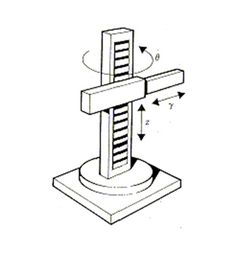

Imagen 1. Modelo

### Procedimiento

Primero se limpia la pantalla y valores, para poder declarar las variables simbólicas, es decir, no tienen un valor en específico.

clear all
close all
clc

%Declaración de variables simbólicas
syms th1(t) long2(t) long3(t)  t  %Angulos de cada articulación
syms th1p(t) long2p(t) long3p(t)    %Velocidades de cada articulación
syms th1pp(t) long2pp(t) long3pp(t)    %Aceleraciones de cada articulación
syms m1 m2 m3 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 Ixx3 Iyy3 Izz3 %Masas 
% y matrices de Inercia
syms l1 l2 l3 lc1 lc2 lc3  %l=longitud de eslabones 
% y lc=distancia al centro de masa de cada eslabón
syms pi g a
altura1=5; %altura constante del robot

Posterioremente se hace la configuración del robot, 0 para junta rotacional, 1 para junta prismática, además de crear el vector de coordenadas articulares (Posición). En este caso, como son 3 articulaciones se colocan 3 elementos en el vector,  analizando el robot de abajo hacia arriba, primero tenemos una articulación rotacional por lo que se pone un cero, las siguientes prosmáticas y se ponen unos.

RP=[0 1 1];

Q= [th1, long2, long3]';
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

/  ______  \
|  th1(t)  |
|          |
| ________ |
| long2(t) |
|          |
| ________ |
\ long3(t) /



Creamos el vector de velocidades generalizadas 

Qp=[th1p, long2p, long3p]';
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  _______  \
|  th1p(t)  |
|           |
| _________ |
| long2p(t) |
|           |
| _________ |
\ long3p(t) /



Creamos el vector de aceleraciones articulares

 Qpp= [th1pp; long2pp; long3pp];
 %disp('Aceleraciones generalizadas');
 pretty (Qpp);

/  th1pp(t)  \
|            |
| long2pp(t) |
|            |
\ long3pp(t) /



Con la función size se declara el número de grados de libertad que tiene el robot con el vector RP previamente definido, se coloca 2 porque indica la dimensión de las columnas y se convierte a string para posteriormente declarar el nombre a las matrices.

GDL= size(RP,2);
GDL_str= num2str(GDL);

Para determinar las matrices de rotación se pone un sistema de referencia en cada articulación empezando desde la base del robot, se coloca el eje z en paralelo con el movimiento de esa articulación y se rota en las demás articulaciones, con esta rotación se determina el ángulo que se sustituirá en las siguientes matrices, dependiendo de en qué eje rotó el sistema de coordenadas.

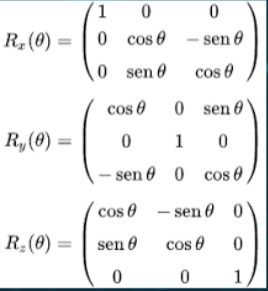

Imagen 2. Matrices de rotación

NOTA: si la rotación fue en la dirección de las manecillas del reloj el ángulo es negativo, de lo contrario es positivo.

%Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [0; 0;l1+altura1];

Como es rotacional sobre su propio eje, no hay dezplazamiento y se sustiyute th1 en cada instante de tiempo en la matriz de rotación.

%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1)  0;
           sin(th1)  cos(th1)  0;
           0         0         1];


En la segunda articulación si hay una translación, para cambiar el marco de referencia rota 90° sobre x, como gira a favor de las manecillas del reloj es un ángulo negativo.

%Articulación 2 
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [0; 0; l2];
%Matriz de rotación de la junta 2 respecto a 1.... -90º
R(:,:,2)= [1 0 0;
           0 0 1;
           0 -1 0];


Para última por practicidad se deja la matriz identidad.

%Articulación 3 
%Posición de la articulación 3 respecto a 2
P(:,:,3)= [0; l3;0];
%Matriz de rotación de la junta 3 respecto a 2
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];

Se crea el vector de ceros y se inicializa tanto las matrices de transformación homogénea locales como las matrices de transformación homogénea globales.

Vector_Zeros= zeros(1, 3);

A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

Se inicializan los vectores de posición vistos desde el marco de referencia inercial con el número de grados de libertad.

PO(:,:,GDL)= P(:,:,GDL); 

Se Inicializan las matrices de rotación vistas desde el marco de referencia inercial con el número de grados de libertad

RO(:,:,GDL)= R(:,:,GDL); 


Ahora en un ciclo for hará el procedimiento el número de veces de grados de libertad que tenga el robot. En este for se despliega las matrices de transformación locales y las globales, con un try catch se hace la excepción si el robot sólo cuenta con un grado de libertad. La mattriz global es la multiplicación de las locales.

for i = 1:GDL
    i_str= num2str(i);
   %disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
   %pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    %pretty(RO(:,:,i));
    %pretty(PO(:,:,i));
end

Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0,    0   \
|                                      |
| sin(th1(t)),  cos(th1(t)), 0,    0   |
|                                      |
|      0,            0,      1, l1 + 5 |
|                                      |
\      0,            0,      0,    1   /



Matriz de Transformación global T2


/ cos(th1(t)),  0, -sin(th1(t)),      0      \
|                                            |
| sin(th1(t)),  0,  cos(th1(t)),      0      |
|                                            |
|      0,      -1,       0,      l1 + l2 + 5 |
|                                            |
\      0,       0,       0,           1      /



Matriz de Transformación global T3


/ cos(th1(t)),  0, -sin(th1(t)),         0        \
|                                                 |
| sin(th1(t)),  0,  cos(th1(t)),         0        |
|                                                 |
|      0,      -1,       0,      l1 + l2 - l3 + 5 |
|                                                 |
\      0,       0,       0,              1        /



Ya con esto se calcula el jacobiano lineal de forma diferencial, para esta matriz se deriva parcialmente th1, long2 y long3, respecto a los ejes. Con las derivadas acomodamos los valores y creamos la matriz del jacobiano.


%Derivadas parciales de x respecto a th1, long2 y long3
Jv11= functionalDerivative(PO(1,1,GDL), th1);
Jv12= functionalDerivative(PO(1,1,GDL), long2);
Jv13= functionalDerivative(PO(1,1,GDL), long3);
%Derivadas parciales de y respecto a th1 y th2
Jv21= functionalDerivative(PO(2,1,GDL), th1);
Jv22= functionalDerivative(PO(2,1,GDL), long2);
Jv23= functionalDerivative(PO(2,1,GDL), long3);
%Derivadas parciales de z respecto a th1 y th2
Jv31= functionalDerivative(PO(3,1,GDL), th1);
Jv32= functionalDerivative(PO(3,1,GDL), long2);
Jv33= functionalDerivative(PO(3,1,GDL), long3);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12 Jv13;
              Jv21 Jv22 Jv23;
              Jv31 Jv32 Jv33]);
%pretty(jv_d);



Ahora se realiza el cálculo del jacobiano lineal de forma analítica, para esto se inicializa los jacobianos analíticos (lineal y angular).

Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

Nuevamente se utiliza un ciclo para construir los jacobianos, con una condición haca el procedimiento para una articulación rotacional o prismática, si en RP es 0 significa que es rotacional y con 1 es prismática,  dentro de la condición hay try catch para los grados de libertad del robot.

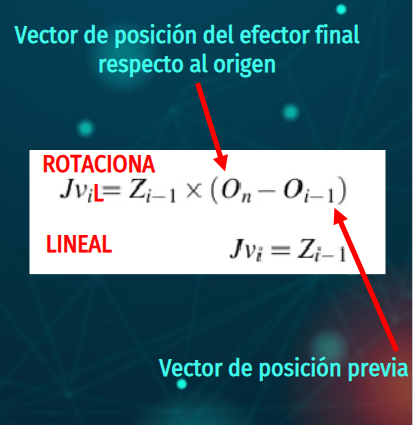

Fórmula 1.

Dependiendo del caso identificado, sea articulación rotacional o lineal, es la fórmula que se emplea.

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 
            % con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa
            % se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    
Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, 0, -sin(th1(t)) \
|                    |
| 0, 0,  cos(th1(t)) |
|                    |
\ 0, 1,       0      /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 1, 0, 0 /



Para finalmente desplegar los resultados con simplify y pretty para tener una visualización más entendible.

disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp);
pretty(V);

/   _________             \
| - long3p(t) sin(th1(t)) |
|                         |
|  _________              |
|  long3p(t) cos(th1(t))  |
|                         |
|        _________        |
\        long2p(t)        /



disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp);
    pretty(W);

/    0    \
|         |
|    0    |
|         |
| _______ |
\ th1p(t) /



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

### **Energía cinética**

Se declara la distancia del origen del eslabón a su centro de masa con vectores de posición respecto al centro de masa.

posteriormente se crea la matriz de inercia por cada eslabón.

 P01=subs(P(:,:,1), l1, lc1); %vector de posición en el eje z
 P12=subs(P(:,:,2), l2, lc2); %vector de posición en el eje y
 P23=subs(P(:,:,3), l3, lc3); %vector de posición en el eje y

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

I3=[Ixx3 0 0; 
    0 Iyy3 0; 
    0 0 Izz3];

**Función de energía cinética**


%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

**Calculamos las velocidades para cada eslabón**

Esta vez necesitamos obtener la velocidad lineal y angular del primer y segundo eslabón, ya que en este robot de tres grados de libertad previamente habíamos calculado las velocidades del último eslabón. A diferencia del robot péndulo, debemos que sacar individualmente las velocidades de cada eslabón.


%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL-2)=PO(:,:,GDL-2);
Jw_a1(:,GDL-2)=PO(:,:,GDL-2);

for k= 1:GDL-2
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-2)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-2));%Matriz de rotación de 0 
            % con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa 
            % se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
 %disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');
Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
%pretty(V1);
% disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');
W1=simplify (Jw_a1*Qp(1));
% pretty(W1);


%Eslabón 2

%Calculamos el jacobiano lineal de forma analítica
Jv_a2(:,GDL-1)=PO(:,:,GDL-1);
Jw_a2(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 
            % con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa 
            % se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');
V2=simplify (Jv_a2*Qp(1:2));
% pretty(V2);
%disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');
W2=simplify (Jw_a2*Qp(1:2));
% pretty(W2);

**Energía cinética para cada eslabón**

Ahora si con las velocidades podemos obtener la energía cinética individual de cada eslabón. Se ocupan los vectores de distancia previamente declarados dependiendo de que eslabón se esté calculando.

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*(1/2*m1*(V1_Total)) + (1/2*W1)'*(I1*W1);
%disp('Energía Cinética en el Eslabón 1');
K1= simplify (K1);
%pretty (K1);


%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*(1/2*m2*(V2_Total)) + (1/2*W2)'*(I2*W2);
%disp('Energía Cinética en el Eslabón 2');
K2= simplify (K2);
%pretty (K2);


%Eslabón 3
V3_Total= V+cross(W,P23);
K3= (1/2*m3*(V3_Total))'*(1/2*m3*(V3_Total)) + (1/2*W)'*(I3*W);
%disp('Energía Cinética en el Eslabón 3');
K3= simplify (K3);
%pretty (K3);

Sumamos las tres energías para desplegar la total

K_Total= simplify (K1+K2+K3);
pretty (K_Total);

                                                                                           2               2           ______             / #2 sin(th1(t))    lc3 #1 \
       2          2                                                    ______      2   |m3|  (th1p(t) |lc3|  + lc3 sin(th1(t)) long3p(t)) | -------------- + ------- |
#3 |m2|    #3 |m3|    Izz1 #1   Izz2 #1   Izz3 #1   #2 cos(th1(t)) cos(th1(t)) |m3|                                                       \    long3p(t)     th1p(t) /
-------- + -------- + ------- + ------- + ------- + -------------------------------- + -------------------------------------------------------------------------------
    4          4         2         2         2                      4                                                       4 lc3

where

                  2
   #1 == |th1p(t)|

                    2
   #2 == |long3p(t)|

                    2
   #3 == |long2p(t)|




#### **Energía potencial**

Calculamos la energía potencial para cada uno de los eslabones.

Primero se obtiene las alturas respecto a la gravedad.

Como la configuración es det tres grado de libertad, se declaran tres alturas.

La primera se declara como la altura constante 

La segunda se iguala a la longitud 2 de la articulación 2, el cual es como un riel.

La tercera también se igualará a la longitud 2 porque también se moverá en el riel de la articulación 2.

De esta manera se obtiene la altura total del robot.

 h1= altura1; %Tomo la altura paralela al eje z
 h2= long2; %Tomo la altura paralela que será la longitud de la segunda articulación.
 h3= long2; %Tomo la altura paralela que será la longitud de la segunda articulación.

Se multiplica las alturas por las masas y la gravedad.

 U1=m1*g*h1;
 U2=m2*g*h2;
 U3=m3*g*h3;

Calculamos la energía potencial total.

 U_Total= U1 + U2 +U3;

Y para obtener el Lagrangiano restamos la energia potencial a la energía cinética.

 Lagrangiano= simplify (K_Total-U_Total);
 %pretty (Lagrangiano);

Para finalmente obtener el modelo de energía sumando la energía cinética y la energía potencial.

 H= simplify (K_Total+U_Total);
 pretty (H)

       2          2                                                                                             ______      2
#3 |m2|    #3 |m3|             Izz1 #1   Izz2 #1   Izz3 #1                                   #2 cos(th1(t)) cos(th1(t)) |m3|
-------- + -------- + 5 g m1 + ------- + ------- + ------- + g m2 long2(t) + g m3 long2(t) + --------------------------------
    4          4                  2         2         2                                                      4

         2               2           ______             / #2 sin(th1(t))    lc3 #1 \
     |m3|  (th1p(t) |lc3|  + lc3 sin(th1(t)) long3p(t)) | -------------- + ------- |
                                                        \    long3p(t)     th1p(t) /
   + -------------------------------------------------------------------------------
                                          4 lc3

where

                  2
   #1 == |th1p(t)|

                    2
   #2 == |long3p(t)|

                    2
   #3 == 

#### Ecuaciones de Movimiento

En esta sección obtenemos el Lagrangiano derivado con respecto a la primera coordenada generalizada de velocidad.

Primero definimos un vector columna de derivadas con respecto al tiempo. En este vector se agregan las velocidades y aceleraciones.

 Qd=[th1p(t); long2p(t); long3p(t); th1pp(t); long2pp(t); long3pp(t)];


 Después obtenemos las derivadas de la velocidad en la primera coordenada generalizada.

 dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), long2),diff(diff(Lagrangiano,th1p), long3),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), long2p),diff(diff(Lagrangiano,th1p), long3p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones


 Obtenemos las derivadas de la velocidad en la segunda coordenada generalizada

 dQ2=[diff(diff(Lagrangiano,long2p), th1),diff(diff(Lagrangiano,long2p), long2),diff(diff(Lagrangiano,long2p), long3),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,long2p), th1p),diff(diff(Lagrangiano,long2p), long2p),diff(diff(Lagrangiano,long2p), long3p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones


  Obtenemos las de derivadas de la velocidad en la tercera coordenada generalizada

 dQ3=[diff(diff(Lagrangiano,long3p), th1),diff(diff(Lagrangiano,long3p), long2),diff(diff(Lagrangiano,long3p), long3),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,long3p), th1p),diff(diff(Lagrangiano,long3p), long2p),diff(diff(Lagrangiano,long3p), long3p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones
 

**Definimos los torques**

 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);

 %Definimos el torque 2
 t2= dQ2*Qd- diff(Lagrangiano, long2);

 %Definimos el torque 3
 t3= dQ3*Qd- diff(Lagrangiano, long3);


**Generación del Modelo Dinámico en forma matricial**

Extraemos coeficientes de aceleraciones y formar la matriz de inercia como resultado.

M=[diff(t1, th1pp), diff(t1, long2pp), diff(t1, long3pp);...
   diff(t2, th1pp), diff(t2, long2pp), diff(t2, long3pp);...
   diff(t3, th1pp), diff(t3, long2pp), diff(t3, long3pp)]

rank (M) %tres grados de libertad

ans = 3

M=M(t);

%se recopila el tiempo que tomó ejecutar las operaciones
toc

Elapsed time is 440.930733 seconds.
